roomspec

ans = struct with fields:
         type: [1 1 1 1 1 1 2 2 2 1 1 1 1 2]
         size: {[3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [2×1 double]  [2×1 double]  [2×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [0.5000 1.5000]}
          pos: {[3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]  [3×1 double]}
          ori: {[3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]}
        color: {[1 0.5000 0]  [1 0.5000 0]  [1 0.5000 0]  [1 0.5000 0]  [0.8000 0 1]  [0.8000 0 1]  [0 1 1]  [0 1 1]  [0 1 1]  [1 0.8000 0.8000]  [1 0.8000 0.8000]  [1 0.8000 0.8000]  [1 0.8000 0.8000]  [0.5000 1 0.5000]}
    normaldir: {[2]}
          obj: {1×14 cell}


%roomshow(colobj, 1);

resolution = 100

resolution = 100

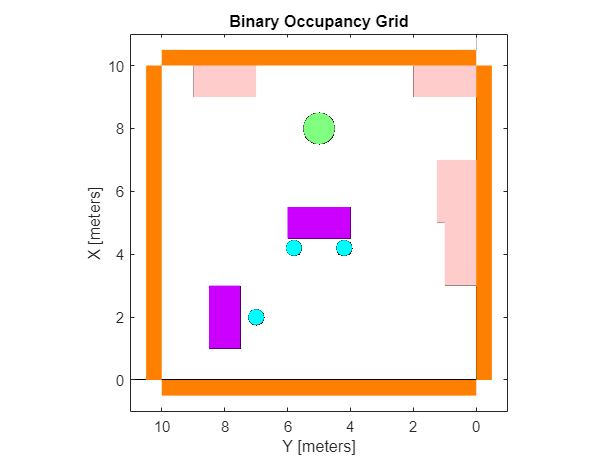

binary_map = binaryOccupancyMap(12,12,resolution);

[X,Y] = meshgrid(0:1/resolution:12,0:1/resolution:12);

for i = 5:length(colobj.obj)
    if colobj.type(i) == 1 % Box
        [xy, xy_ones] = occupancy_rect(X, Y, ...
            colobj.size{i}(1), ...
            colobj.size{i}(2), ...
            colobj.pos{i}(1), ...
            colobj.pos{i}(2));
        setOccupancy(binary_map, xy, xy_ones);
    elseif colobj.type(i) == 2 % Cylinder
        [xy, xy_ones] = occupancy_circle(X, Y, ...
            colobj.size{i}(1), ...
            colobj.pos{i}(1), ...
            colobj.pos{i}(2));
        setOccupancy(binary_map, xy, xy_ones);
    else
        disp('Not supported')
    end
end

% Make walls
ind = (X == min(X(:))) | (X == max(X(:))) | (Y == min(Y(:))) | (Y == max(Y(:)));
x = X(ind);
y = Y(ind);
xy = [x y];
xy_ones = ones(size(x));
setOccupancy(binary_map, xy, xy_ones);

inflate(binary_map, 1/resolution)

show(binary_map)
axis equal
grid on
hold on
roomshow(colobj, 1);
hold off

i = 5

i = 5

binary_map = binaryOccupancyMap(12,12,resolution);
[xy, xy_ones] = occupancy_rect(X, Y, ...
    colobj.size{i}(1), ...
    colobj.size{i}(2), ...
    colobj.pos{i}(1), ...
    colobj.pos{i}(2));
M = X

M =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0

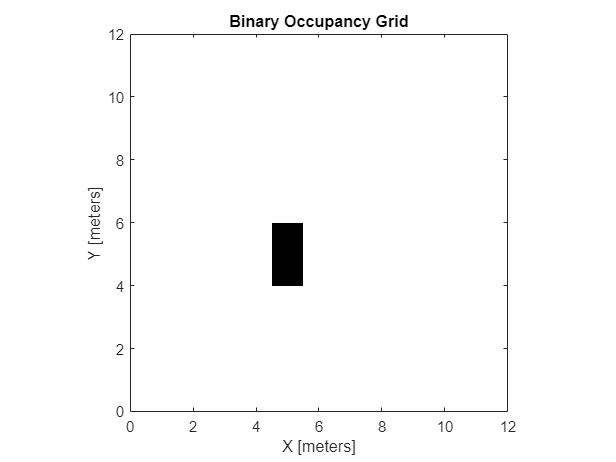


setOccupancy(binary_map, xy, xy_ones);

show(binary_map)

function [xy, xy_ones] = occupancy_circle(X, Y, r, x_c, y_c)
ind = (X-x_c).^2 + (Y-y_c).^2 <= r^2;
x = X(ind);
y = Y(ind);
xy = [x y];
xy_ones = ones(size(x));
end

function [xy, xy_ones] = occupancy_rect(X, Y, x_w, y_w, x_c, y_c)
ind = abs(X - x_c)*2 < x_w & abs(Y - y_c)*2 < y_w;
x = X(ind);
y = Y(ind);
xy = [x y];
xy_ones = ones(size(x));
end